## **clcLoad data**

% Cortical amygdala
coa15 = load('coa_15_2_2.mat');
coaAA = load('coa_AAmix_2_2.mat');
coaCS = load('coa_CS_2_2.mat');
coa151 = load('coa_15_2_1.mat');
coaAA1 = load('coa_AAmix_2_1.mat');
coaCS1 = load('coa_CS_2_1.mat');

% Piriform cortex
pcx15 = load('pcx_15_2_2.mat');
pcxAA = load('pcx_AAmix_2_2.mat');
pcxCS = load('pcx_CS_2_2.mat');
pcx151 = load('pcx_15_2_1.mat');
pcxAA1 = load('pcx_AAmix_2_1.mat');
pcxCS1 = load('pcx_CS_2_1.mat');

% Number of odors
odors = 1:15; 
% Colors
coaC = [227,26,28] ./ 255;
pcxC = [82,82,82]./255;
labelC = [37,37,37] ./ 255;

## Number of units

idxU = 0;
coaUnits = {coa15.esp, coaAA.esp, coaCS.esp};
for idx = 1:3
    esp = coaUnits{idx};
    for idxExp = 1:length(esp)
        for idxShank = 1:4
            for idxUnit = 1:length((esp(idxExp).shankNowarp(idxShank).cell));
                if esp(idxExp).shankNowarp(idxShank).cell(idxUnit).good == 1
                    idxU = idxU + 1;
                end
            end
        end
    end
end
coaCells = idxU;

idxU = 0;
pcxUnits = {pcx15.esp, pcxAA.esp, pcxCS.esp};
for idx = 1:3
    esp = pcxUnits{idx};
    for idxExp = 1:length(esp)
        for idxShank = 1:4
            for idxUnit = 1:length((esp(idxExp).shankNowarp(idxShank).cell));
                if esp(idxExp).shankNowarp(idxShank).cell(idxUnit).good == 1
                    idxU = idxU + 1;
                end
            end
        end
    end
end
pcxCells = idxU;


## **Extract baseline firing, change of spike counts, Fano factor and auROC - 300 ms**

[Bslcoa15, DeltaRspcoa15, rspMeancoa15, rspVarcoa15, ffcoa15, cvcoa15, auRoccoa15, varGcoa15, significancecoa15] = find_Baseline_DeltaRsp_FanoFactor(coa15.esp, odors, 300);

[BslcoaAA, DeltaRspcoaAA, rspMeancoaAA, rspVarcoaAA, ffcoaAA, cvcoaAA, auRoccoaAA, varGcoaAA, significancecoaAA] = find_Baseline_DeltaRsp_FanoFactor(coaAA.esp, odors, 300);
[Bslpcx15, DeltaRsppcx15, rspMeanpcx15, rspVarpcx15, ffpcx15, cvpcx15, auRocpcx15, varGpcx15, significancepcx15] = find_Baseline_DeltaRsp_FanoFactor(pcx15.esp, odors, 300);
[BslpcxAA, DeltaRsppcxAA, rspMeanpcxAA, rspVarpcxAA, ffpcxAA, cvpcxAA, auRocpcxAA, varGpcxAA, significancepcxAA] = find_Baseline_DeltaRsp_FanoFactor(pcxAA.esp, odors, 300);

## **Plot baseline**

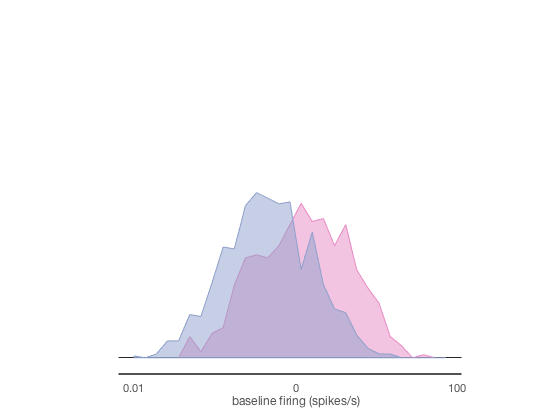

allBsl = [Bslcoa15 BslcoaAA Bslpcx15 BslpcxAA];
maxBsl = max(allBsl);
minBsl = min(allBsl);
edges = logspace(-2,2,30);
[N1,edges] = histcounts([Bslpcx15 BslpcxAA], edges,'normalization', 'probability');
[N2,edges] = histcounts([Bslcoa15 BslcoaAA], edges,'normalization', 'probability');
edges = log10(edges(1:end-1));

xMargin = 0.05 * range(edges);
bottomMargin = 0.01;
topMargin = 0.001;
leftX = min(edges);
rightX = max(edges);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

h1 = area(edges, N1);
h1.FaceColor = pcxC;
h1.EdgeColor = pcxC;
alpha(h1, 0.5)
hold on; 
h2 = area(edges, N2);
h2.FaceColor = coaC;
h2.EdgeColor = coaC;
alpha(h2, 0.5)


clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'baseline firing (spikes/s)';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabelLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {'0.01', num2str(0), '100'};
axP.axisOffset = 0-bottomMargin;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

## **Plot change in spikes emitted**

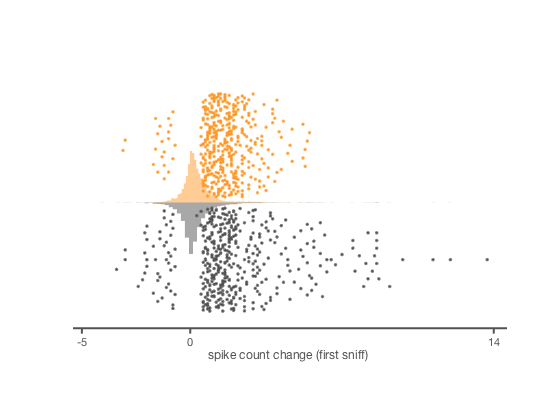

DeltaRspCOA = [DeltaRspcoa15;DeltaRspcoaAA];
DeltaRspPCX = [DeltaRsppcx15;DeltaRsppcxAA];
logSignificantCoa = [significancecoa15; significancecoaAA];
logSignificantCoa = logSignificantCoa(:);
logSignificantPcx = [significancepcx15; significancepcxAA];
logSignificantPcx = logSignificantPcx(:);

xMargin = 0.05 * range([DeltaRspCOA(:); DeltaRspPCX(:)]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([DeltaRspCOA(:); DeltaRspPCX(:)]);
rightX = max([DeltaRspCOA(:); DeltaRspPCX(:)]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

distributionPlot(DeltaRspCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
distributionPlot(DeltaRspPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
hold on
coaRsp = DeltaRspCOA;
coaRsp(logSignificantCoa == 0) = [];
pcxRsp = DeltaRspPCX;
pcxRsp(logSignificantPcx == 0) = [];
dataToPlot = {pcxRsp,coaRsp};
catIdx = [ones(length(pcxRsp),1); zeros(length(coaRsp),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)

clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'spike count change (first sniff)';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

## Plot Fano Factor

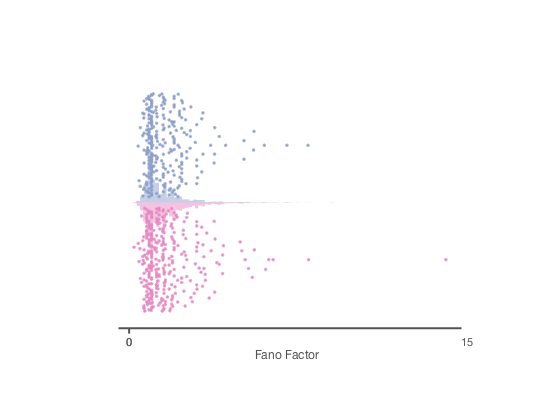

ffCOA = [ffcoa15(:); ffcoaAA(:)];
%ffCOA = ffCOA(~isnan(ffCOA)); ffCOA = ffCOA(~isinf(ffCOA)); %ffCOA = ffCOA(ffCOA<40);
%logSignificantCoa = logSignificantCoa(~isnan(ffCOA)); logSignificantCoa = logSignificantCoa(~isinf(ffCOA)); %logSignificantCoa = logSignificantCoa(ffCOA<40);
ffCoaSig = ffCOA;
ffCoaSig(logSignificantCoa <1) = [];

ffPCX = [ffpcx15(:); ffpcxAA(:)];
%ffPCX = ffPCX(~isnan(ffPCX)); ffPCX = ffPCX(~isinf(ffPCX)); %ffPCX = ffPCX(ffPCX<40);
%logSignificantPcx = logSignificantPcx(~isnan(ffPCX)); logSignificantPcx = logSignificantPcx(~isinf(ffPCX)); %logSignificantPcx = logSignificantPcx(ffPCX<40);
ffPcxSig = ffPCX;
ffPcxSig(logSignificantPcx < 1) = [];

xMargin = 0.05 * range([ffCoaSig; ffPcxSig]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([ffCoaSig; ffPcxSig]);
rightX = max([ffCoaSig; ffPcxSig]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);
distributionPlot(ffCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
distributionPlot(ffPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
hold on
dataToPlot = {ffPcxSig,ffCoaSig};
catIdx = [ones(length(ffPcxSig),1); zeros(length(ffCoaSig),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)
clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'Fano Factor (fist sniff)';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

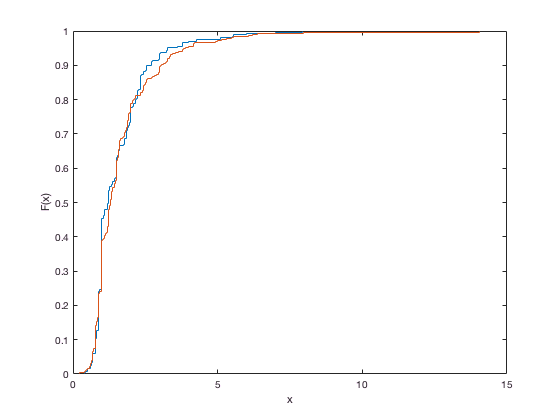


figure
ecdf(ffCoaSig)
hold on
ecdf(ffPcxSig)
hold off

% 

## Mean vs Variance

app1 = [rspMeancoa15(:); rspMeancoaAA(:)];
app2 = [rspVarcoa15(:); rspVarcoaAA(:)];
logSignificantCoa = [significancecoa15(:); significancecoaAA(:)];
% app1 = [rspMeancoa15(:)];
% app2 = [rspVarcoa15(:)];
% logSignificantCoa = [significancecoa15(:)];
% app1 = [rspMeancoaAA(:)];
% app2 = [rspVarcoaAA(:)];
% logSignificantCoa = [significancecoaAA(:)];
meanRspCoa = app1(logSignificantCoa==1);
varRspCoa = app2(logSignificantCoa==1);
xMargin = 0.05 * range(meanRspCoa);
yMargin = 0.05 * range(varRspCoa);
leftX = min(meanRspCoa);
rightX = max(meanRspCoa);
bottomY = min(varRspCoa);
topY = max(varRspCoa);
blankFigure([leftX-xMargin rightX+xMargin bottomY-yMargin topY+yMargin]);
plot(meanRspCoa, varRspCoa, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', coaC, 'MarkerFaceColor', coaC);

clear axX
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axX.lineThickness = 2;
axX.axisLabel = 'Mean (spike count) - first sniff';
axX.axisOrientation = 'h';
axX.tickLocations = [floor(leftX) ceil(rightX)];
axX.tickLabels = {num2str(floor(leftX)) num2str(ceil(rightX))};
axX.axisOffset = bottomY - yMargin;
axX.fontSize = 12; 
axX.color = labelC; 
AxisMMC(start, fin, axX);

clear axY
start = floor(bottomY-yMargin);
fin = ceil(topY+yMargin);
axY.lineThickness = 2;
axY.axisLabel = 'Variance (spike count)';
axY.axisOrientation = 'v';
axY.tickLocations = [floor(bottomY) ceil(topY)];
axY.tickLabels = {num2str(floor(bottomY)) num2str(ceil(topY))};
axY.axisOffset = leftX - xMargin;
axY.fontSize = 12; 
axY.color = labelC; 
AxisMMC(start, fin, axY);
hold on
fun = @(x,meanRspCoa)meanRspCoa + x(1)*meanRspCoa.^2

fun =     @(x,meanRspCoa)meanRspCoa+x(1)*meanRspCoa.^2


x0 = [0,0];
x = lsqcurvefit(fun,x0,meanRspCoa,varRspCoa);


Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>



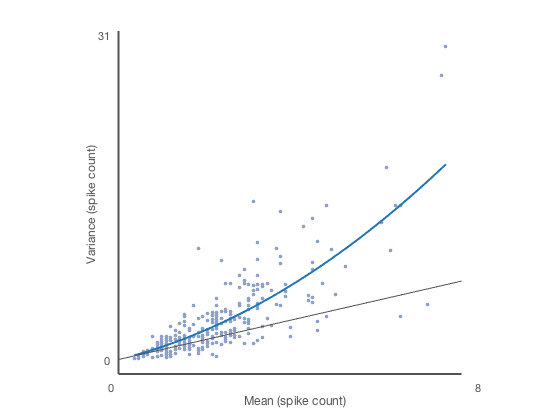

xAx = linspace(min(meanRspCoa),max(meanRspCoa));
plot(xAx,fun(x,xAx),'-', 'color', coaC, 'linewidth', 2)
h = line([0 max(varRspCoa)], [0 max(varRspCoa)], 'linewidth', 1, 'color', labelC);
hold off


app1 = [rspMeanpcx15(:); rspMeanpcxAA(:)];
app2 = [rspVarpcx15(:); rspVarpcxAA(:)];
logSignificantPcx = [significancepcx15(:); significancepcxAA(:)];
% app1 = [rspMeanpcx15(:)];
% app2 = [rspVarpcx15(:)];
% logSignificantPcx = [significancepcx15(:)];
% app1 = [rspMeanpcxAA(:)];
% app2 = [rspVarpcxAA(:)];
% logSignificantPcx = [significancepcxAA(:)];
meanRspPcx = app1(logSignificantPcx==1);
varRspPcx = app2(logSignificantPcx==1);
xMargin = 0.05 * range(meanRspPcx);
yMargin = 0.05 * range(varRspPcx);
leftX = min(meanRspPcx);
rightX = max(meanRspPcx);
bottomY = min(varRspPcx);
topY = max(varRspPcx);
blankFigure([leftX-xMargin rightX+xMargin bottomY-yMargin topY+yMargin]);
plot(meanRspPcx, varRspPcx, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', pcxC, 'MarkerFaceColor', pcxC);


clear axX
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axX.lineThickness = 2;
axX.axisLabel = 'Mean (spike count) - first sniff';
axX.axisOrientation = 'h';
axX.tickLocations = [floor(leftX) ceil(rightX)];
axX.tickLabels = {num2str(floor(leftX)) num2str(ceil(rightX))};
axX.axisOffset = bottomY - yMargin;
axX.fontSize = 12; 
axX.color = labelC; 
AxisMMC(start, fin, axX);

clear axY
start = floor(bottomY-yMargin);
fin = ceil(topY+yMargin);
axY.lineThickness = 2;
axY.axisLabel = 'Variance (spike count)';
axY.axisOrientation = 'v';
axY.tickLocations = [floor(bottomY) ceil(topY)];
axY.tickLabels = {num2str(floor(bottomY)) num2str(ceil(topY))};
axY.axisOffset = leftX - xMargin;
axY.fontSize = 12; 
axY.color = labelC; 
AxisMMC(start, fin, axY);

hold on
fun = @(x,meanRspPcx)meanRspPcx(meanRspPcx<22) + x(1)*meanRspPcx(meanRspPcx<22).^2;
% fun = @(x,meanRspPcx)meanRspPcx + x(1)*meanRspPcx.^2
x0 = [0,0];
x1 = lsqcurvefit(fun,x0,meanRspPcx(meanRspPcx<22),varRspPcx(meanRspPcx<22));


Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>



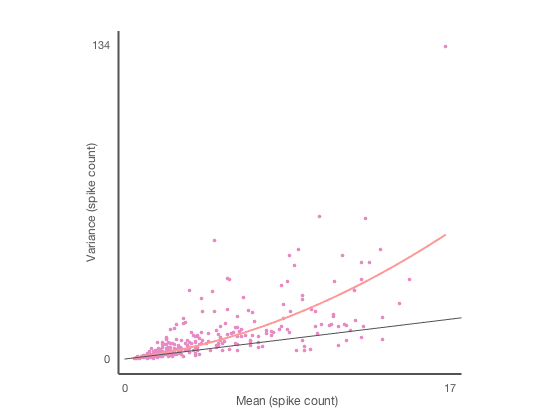

xAx = linspace(min(meanRspPcx(meanRspPcx<22)),max(meanRspPcx(meanRspPcx<22)));
% x1 = lsqcurvefit(fun,x0,meanRspPcx,varRspPcx);
% xAx = linspace(min(meanRspPcx),max(meanRspPcx));
plot(xAx,fun(x1,xAx),'-', 'color', pcxC, 'linewidth', 2)
h = line([0 max(varRspPcx)], [0 max(varRspPcx)], 'linewidth', 1, 'color', labelC);
hold off

## auROC

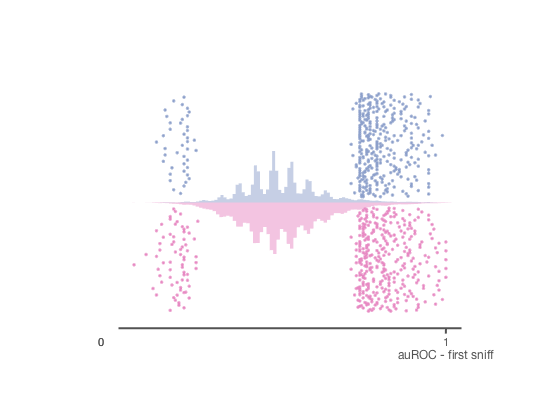

auROCCOA = [auRoccoa15;auRoccoaAA];
auROCPCX = [auRocpcx15;auRocpcxAA];
logSignificantCoa = [significancecoa15; significancecoaAA];
logSignificantCoa = logSignificantCoa(:);
logSignificantPcx = [significancepcx15; significancepcxAA];
logSignificantPcx = logSignificantPcx(:);

xMargin = 0.05 * range([auROCCOA(:); auROCPCX(:)]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([auROCCOA(:); auROCPCX(:)]);
rightX = max([auROCCOA(:); auROCPCX(:)]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

distributionPlot(auROCCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
distributionPlot(auROCPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
hold on
coaRsp = auROCCOA;
coaRsp(logSignificantCoa == 0) = [];
pcxRsp = auROCPCX;
pcxRsp(logSignificantPcx == 0) = [];
dataToPlot = {pcxRsp,coaRsp};
catIdx = [ones(length(pcxRsp),1); zeros(length(coaRsp),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)

clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'auROC - first sniff';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

## **Extract baseline firing, change of spike counts, Fano factor and auROC - 1000 ms**

% [Bslcoa15, Bslcoa15All, DeltaRspcoa15, DeltaRspcoaTrials15, DeltaRspExcSigcoa15, DeltaRspInhSigcoa15, rspMeancoa15, rspVarcoa15, ffcoa15, cvcoa15, auRoccoa15, varGcoa15, rspFractioncoa15Exc, rspFractioncoa15Inh, significancecoa15] = find_Baseline_DeltaRsp_FanoFactor(coa15.esp, odors, 1000);
% [BslcoaAA, BslcoaAAAll, DeltaRspcoaAA, DeltaRspcoaTrialsAA, DeltaRspExcSigcoaAA, DeltaRspInhSigcoaAA,  rspMeancoaAA, rspVarcoaAA, ffcoaAA, cvcoaAA, auRoccoaAA, varGcoaAA, rspFractioncoaAAExc, rspFractioncoaAAInh, significancecoaAA] = find_Baseline_DeltaRsp_FanoFactor(coaAA.esp, odors, 1000);
% [Bslpcx15, Bslpcx15All, DeltaRsppcx15, DeltaRsppcxTrials15, DeltaRspExcSigpcx15, DeltaRspInhSigpcx15,  rspMeanpcx15, rspVarpcx15, ffpcx15, cvpcx15, auRocpcx15, varGpcx15, rspFractionpcx15Exc, rspFractionpcx15Inh, significancepcx15] = find_Baseline_DeltaRsp_FanoFactor(pcx15.esp, odors, 1000);
% [BslpcxAA, BslpcxAAAll, DeltaRsppcxAA, DeltaRsppcxTrialsAA, DeltaRspExcSigpcxAA, DeltaRspInhSigpcxAA,  rspMeanpcxAA, rspVarpcxAA, ffpcxAA, cvpcxAA, auRocpcxAA, varGpcxAA, rspFractionpcxAAExc, rspFractionpcxAAInh,significancepcxAA] = find_Baseline_DeltaRsp_FanoFactor(pcxAA.esp, odors, 1000);
Mcoa15 = find_Baseline_DeltaRsp_FanoFactor(coa15.esp, odors, 1000);
McoaAA = find_Baseline_DeltaRsp_FanoFactor(coaAA.esp, odors, 1000);
Mpcx15 = find_Baseline_DeltaRsp_FanoFactor(pcx15.esp, odors, 1000);
MpcxAA = find_Baseline_DeltaRsp_FanoFactor(pcxAA.esp, odors, 1000);
McoaCS = find_Baseline_DeltaRsp_FanoFactor(coaCS.esp, odors, 1000);
MpcxCS = find_Baseline_DeltaRsp_FanoFactor(pcxCS.esp, odors, 1000);
logSignificantCoa = [Mcoa15.significance; McoaAA.significance];
logSignificantCoa = logSignificantCoa(:);
logSignificantPcx = [Mpcx15.significance; MpcxAA.significance];
logSignificantPcx = logSignificantPcx(:);

## **Plot baseline**

allBsl = [Mcoa15.Bsl McoaAA.Bsl Mpcx15.Bsl MpcxAA.Bsl];
maxBsl = max(allBsl);
minBsl = min(allBsl);
edges = logspace(-2,2,30);
[N1,edges] = histcounts([Mpcx15.Bsl MpcxAA.Bsl], edges,'normalization', 'probability');
[N2,edges] = histcounts([Mcoa15.Bsl McoaAA.Bsl], edges,'normalization', 'probability');
edges = log10(edges(1:end-1));

xMargin = 0.05 * range(edges);
bottomMargin = 0.01;
topMargin = 0.001;
leftX = min(edges);
rightX = max(edges);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

h1 = area(edges, N1);
h1.FaceColor = pcxC;
h1.EdgeColor = pcxC;
alpha(h1, 0.5)
hold on; 
h2 = area(edges, N2);
h2.FaceColor = coaC;
h2.EdgeColor = coaC;
alpha(h2, 0.5)


clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'baseline firing (spikes/s)';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabelLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {'0.01', num2str(0), '100'};
axP.axisOffset = 0-bottomMargin;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

## **Plot change in spikes emitted**

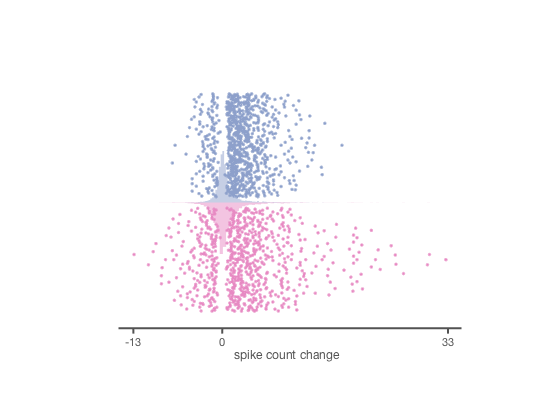

DeltaRspCOA = [DeltaRspcoa15;DeltaRspcoaAA];
DeltaRspPCX = [DeltaRsppcx15;DeltaRsppcxAA];


xMargin = 0.05 * range([DeltaRspCOA(:); DeltaRspPCX(:)]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([DeltaRspCOA(:); DeltaRspPCX(:)]);
rightX = max([DeltaRspCOA(:); DeltaRspPCX(:)]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

distributionPlot(DeltaRspCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
distributionPlot(DeltaRspPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
hold on
coaRsp = DeltaRspCOA;
coaRsp(logSignificantCoa == 0) = [];
pcxRsp = DeltaRspPCX;
pcxRsp(logSignificantPcx == 0) = [];
dataToPlot = {pcxRsp,coaRsp};
catIdx = [ones(length(pcxRsp),1); zeros(length(coaRsp),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)

clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'spike count change (first second)';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

## Plot Fano Factor

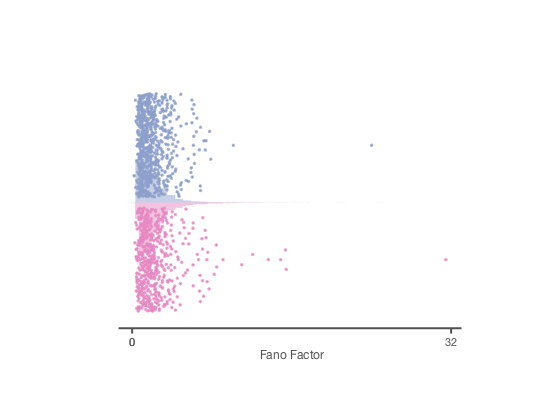

ffCOA = [Mcoa15.ff(:); McoaAA.ff(:)];
%ffCOA = ffCOA(~isnan(ffCOA)); ffCOA = ffCOA(~isinf(ffCOA)); %ffCOA = ffCOA(ffCOA<40);
%logSignificantCoa = logSignificantCoa(~isnan(ffCOA)); logSignificantCoa = logSignificantCoa(~isinf(ffCOA)); %logSignificantCoa = logSignificantCoa(ffCOA<40);
ffCoaSig = ffCOA;
ffCoaSig(logSignificantCoa <1) = [];

ffPCX = [Mpcx15.ff(:); MpcxAA.ff(:)];
%ffPCX = ffPCX(~isnan(ffPCX)); ffPCX = ffPCX(~isinf(ffPCX)); %ffPCX = ffPCX(ffPCX<40);
%logSignificantPcx = logSignificantPcx(~isnan(ffPCX)); logSignificantPcx = logSignificantPcx(~isinf(ffPCX)); %logSignificantPcx = logSignificantPcx(ffPCX<40);
ffPcxSig = ffPCX;
ffPcxSig(logSignificantPcx < 1) = [];


figure
x = distributionPlot(ffCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped');
y = distributionPlot(ffPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped');
alpha(0.5)
x1 = ffCOA(ffCOA<20.1);
y1 = ffPCX(ffPCX<20.1);
edges = 0:0.2:max([ffCOA(:); ffPCX(:)]);
x = histcounts(ffCOA(:), 'normalization', 'probability');
y = histcounts(ffPCX(:), 'normalization', 'probability');
figure
h = plot(x);
h.Color = coaC;
set(gcf,'color','white', 'PaperPositionMode', 'auto');
set(gca, 'box', 'off', 'tickDir', 'out', 'fontname', 'avenir', 'fontsize', 14)
figure
h = plot(y)
h.Color = pcxC;
set(gcf,'color','white', 'PaperPositionMode', 'auto');
set(gca, 'box', 'off', 'tickDir', 'out', 'fontname', 'avenir', 'fontsize', 14)


figure
dataToPlot = {ffPcxSig,ffCoaSig};
catIdx = [ones(length(ffPcxSig),1); zeros(length(ffCoaSig),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')




xMargin = 0.05 * range([ffCoaSig; ffPcxSig]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([ffCoaSig; ffPcxSig]);
rightX = max([ffCoaSig; ffPcxSig]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);
distributionPlot(ffCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
distributionPlot(ffPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
hold on
dataToPlot = {ffPcxSig,ffCoaSig};
catIdx = [ones(length(ffPcxSig),1); zeros(length(ffCoaSig),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)
clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'Fano Factor (first second)';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

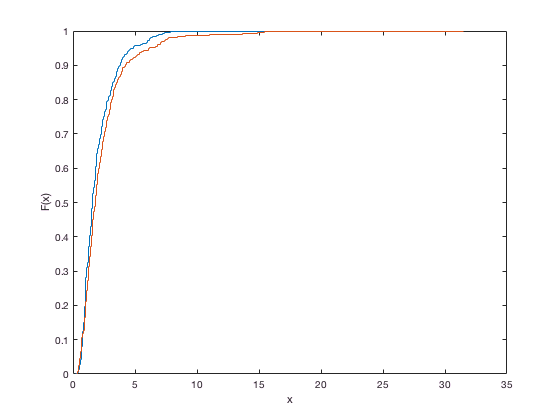


figure
ecdf(ffCoaSig)
hold on
ecdf(ffPcxSig)
hold off

% 

## Mean vs Variance

app1 = [rspMeancoa15(:); rspMeancoaAA(:)];
app2 = [rspVarcoa15(:); rspVarcoaAA(:)];
logSignificantCoa = [significancecoa15(:); significancecoaAA(:)];
% app1 = [rspMeancoa15(:)];
% app2 = [rspVarcoa15(:)];
% logSignificantCoa = [significancecoa15(:)];
% app1 = [rspMeancoaAA(:)];
% app2 = [rspVarcoaAA(:)];
% logSignificantCoa = [significancecoaAA(:)];
meanRspCoa = app1(logSignificantCoa==1);
varRspCoa = app2(logSignificantCoa==1);
xMargin = 0.05 * range(meanRspCoa);
yMargin = 0.05 * range(varRspCoa);
leftX = min(meanRspCoa);
rightX = max(meanRspCoa);
bottomY = min(varRspCoa);
topY = max(varRspCoa);
blankFigure([leftX-xMargin rightX+xMargin bottomY-yMargin topY+yMargin]);
plot(meanRspCoa, varRspCoa, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', coaC, 'MarkerFaceColor', coaC);

clear axX
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axX.lineThickness = 2;
axX.axisLabel = 'Mean (spike count) - first second';
axX.axisOrientation = 'h';
axX.tickLocations = [floor(leftX) ceil(rightX)];
axX.tickLabels = {num2str(floor(leftX)) num2str(ceil(rightX))};
axX.axisOffset = bottomY - yMargin;
axX.fontSize = 12; 
axX.color = labelC; 
AxisMMC(start, fin, axX);

clear axY
start = floor(bottomY-yMargin);
fin = ceil(topY+yMargin);
axY.lineThickness = 2;
axY.axisLabel = 'Variance (spike count)';
axY.axisOrientation = 'v';
axY.tickLocations = [floor(bottomY) ceil(topY)];
axY.tickLabels = {num2str(floor(bottomY)) num2str(ceil(topY))};
axY.axisOffset = leftX - xMargin;
axY.fontSize = 12; 
axY.color = labelC; 
AxisMMC(start, fin, axY);
hold on
x = meanRspCoa;
y = meanRspCoa + meanRspCoa.^2 * 0.3;
fun = @(x,meanRspCoa)meanRspCoa + x(1)*meanRspCoa.^2

fun =     @(x,meanRspCoa)meanRspCoa+x(1)*meanRspCoa.^2


x0 = [0,0];
x = lsqcurvefit(fun,x0,meanRspCoa,varRspCoa);


Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>



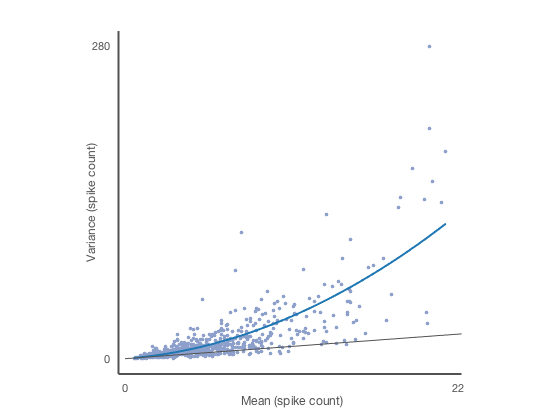

xAx = linspace(min(meanRspCoa),max(meanRspCoa));

% g1 = partNeuralVariance(floor(meanRspCoa));
% plot(floor(meanRspCoa),floor(meanRspCoa) + g1.*floor(meanRspCoa).^2,'s', 'color', [31,120,180]/255, 'markersize', 5)
plot(xAx,fun(x,xAx),'-', 'color', coaC, 'linewidth', 2)
h = line([0 max(varRspCoa)], [0 max(varRspCoa)], 'linewidth', 1, 'color', labelC);
hold off


app1 = [rspMeanpcx15(:); rspMeanpcxAA(:)];
app2 = [rspVarpcx15(:); rspVarpcxAA(:)];
logSignificantPcx = [significancepcx15(:); significancepcxAA(:)];
% app1 = [rspMeanpcx15(:)];
% app2 = [rspVarpcx15(:)];
% logSignificantPcx = [significancepcx15(:)];
% app1 = [rspMeanpcxAA(:)];
% app2 = [rspVarpcxAA(:)];
% logSignificantPcx = [significancepcxAA(:)];
meanRspPcx = app1(logSignificantPcx==1);
varRspPcx = app2(logSignificantPcx==1);
xMargin = 0.05 * range(meanRspPcx);
yMargin = 0.05 * range(varRspPcx);
leftX = min(meanRspPcx);
rightX = max(meanRspPcx);
bottomY = min(varRspPcx);
topY = max(varRspPcx);
blankFigure([leftX-xMargin rightX+xMargin bottomY-yMargin topY+yMargin]);
plot(meanRspPcx, varRspPcx, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', pcxC, 'MarkerFaceColor', pcxC);


clear axX
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axX.lineThickness = 2;
axX.axisLabel = 'Mean (spike count) - first second';
axX.axisOrientation = 'h';
axX.tickLocations = [floor(leftX) ceil(rightX)];
axX.tickLabels = {num2str(floor(leftX)) num2str(ceil(rightX))};
axX.axisOffset = bottomY - yMargin;
axX.fontSize = 12; 
axX.color = labelC; 
AxisMMC(start, fin, axX);

clear axY
start = floor(bottomY-yMargin);
fin = ceil(topY+yMargin);
axY.lineThickness = 2;
axY.axisLabel = 'Variance (spike count)';
axY.axisOrientation = 'v';
axY.tickLocations = [floor(bottomY) ceil(topY)];
axY.tickLabels = {num2str(floor(bottomY)) num2str(ceil(topY))};
axY.axisOffset = leftX - xMargin;
axY.fontSize = 12; 
axY.color = labelC; 
AxisMMC(start, fin, axY);

hold on
fun = @(x,meanRspPcx)meanRspPcx(meanRspPcx<22) + x(1)*meanRspPcx(meanRspPcx<22).^2;
% fun = @(x,meanRspPcx)meanRspPcx + x(1)*meanRspPcx.^2
x0 = [0,0];
x1 = lsqcurvefit(fun,x0,meanRspPcx(meanRspPcx<22),varRspPcx(meanRspPcx<22));


Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>



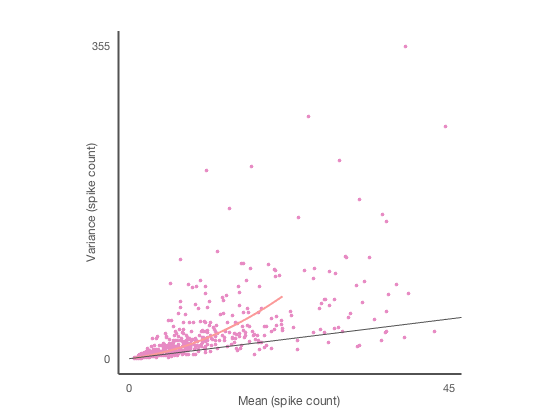

xAx = linspace(min(meanRspPcx(meanRspPcx<22)),max(meanRspPcx(meanRspPcx<22)));
% x1 = lsqcurvefit(fun,x0,meanRspPcx,varRspPcx);
% xAx = linspace(min(meanRspPcx),max(meanRspPcx));
% g2 = partNeuralVariance(floor(meanRspPcx));
% plot(floor(meanRspPcx),floor(meanRspPcx) + g2.*floor(meanRspPcx).^2,'s', 'color', [251,154,153]/255, 'markersize', 5)
plot(xAx,fun(x1,xAx),'-', 'color', pcxC, 'linewidth', 2)
h = line([0 max(varRspPcx)], [0 max(varRspPcx)], 'linewidth', 1, 'color', labelC);
hold off

## Simulation of a negative binomial neuron

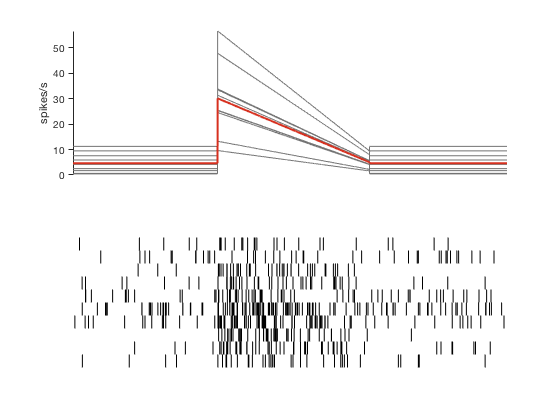

%%
delta = 0.001;
time = 0:delta:30;
time(end-1:end) = [];
x = ones(1,29999);
r = length(x(15000:17099));
lambdaRest = 5;
lambdaResp = linspace(30,5,r);
offset = 4;
baseline1 = x(1:15000) * lambdaRest;
baseline2 = x(17100:29999) * lambdaRest;
response = x(15000:17099) .* lambdaResp;

Fs = 1000;
%Period
t = 0:1/Fs:30;
t(end-1:end) = [];
%Frequency
f = 3;
%Generate
resp = sin(2*pi*f*t);



varianzaG_rest = 0.8;
r_rest = 1/varianzaG_rest;
s_rest = varianzaG_rest;
varianzaG_resp = 0.2;
r_resp = 1/varianzaG_resp;
s_resp = varianzaG_resp;
numRealizations = 1;
clear spikeCollSim
clear lambda
for idxTrial = 1:100
    G_rest = gamrnd(r_rest,s_rest);
    G_resp = gamrnd(r_resp,s_resp);
    bsl1 = baseline1 * G_rest;
    bsl2 = baseline2 * G_rest;
    rsp = response * G_resp;
    trace = [bsl1 rsp bsl2];
    trace(end) = [];
%     trace = trace.* resp;
    mu(idxTrial,:) = trace;
    lambda = Covariate(time,trace, '\lambda(t)','time','s',...
        'spikes/sec',{'\lambda_{1}'},{{' ''b'', ''LineWidth'' ,2'}});
    spikeCollSim{idxTrial} = CIF.simulateCIFByThinningFromLambda(lambda,numRealizations);
    a{idxTrial} = spikeCollSim{idxTrial}.nstrain{1,1}.spikeTimes;
    spikeCount(idxTrial) = numel(a{idxTrial}(find(a{idxTrial}>15 & a{idxTrial}<17)));
    
        G_rest = 1;
    G_resp = 1;
    bsl1 = baseline1 * G_rest;
    bsl2 = baseline2 * G_rest;
    rsp = response * G_resp;
    trace = [bsl1 rsp bsl2];
    trace(end) = [];
    muP(idxTrial,:) = trace;
    lambdaP = Covariate(time,trace, '\lambda(t)','time','s',...
        'spikes/sec',{'\lambda_{1}'},{{' ''b'', ''LineWidth'' ,2'}});
    spikeCollSimP{idxTrial} = CIF.simulateCIFByThinningFromLambda(lambdaP,numRealizations);
    b{idxTrial} = spikeCollSimP{idxTrial}.nstrain{1,1}.spikeTimes;
    spikeCountP(idxTrial) = numel(b{idxTrial}(find(b{idxTrial}>15 & b{idxTrial}<17)));
end

figure
subplot(2,1,1)
hold on
for idxTrial = 1:100
    plot(time, mu(idxTrial,:), 'color', [115,115,115]./255);
end
plot(time, mean(mu), 'color', [215,48,31]./255, 'linewidth', 2); 
xlim([13 19]);
ylim([0 max(mu(:))]);
ylabel('spikes/s')
set(gca, 'XTick' , []);
set(gca, 'XTickLabel', []);
set(gca,'XColor','w')
set(gca,'TickDir','out')
hold off
subplot(2,1,2)
LineFormat.Color =  'k';
plotSpikeRaster(a,'PlotType','vertline', 'VertSpikeHeight', 1,'XLimForCell',[13 19], 'LineFormat', LineFormat);
set(gca,'XColor','w')
set(gca,'YColor','w')

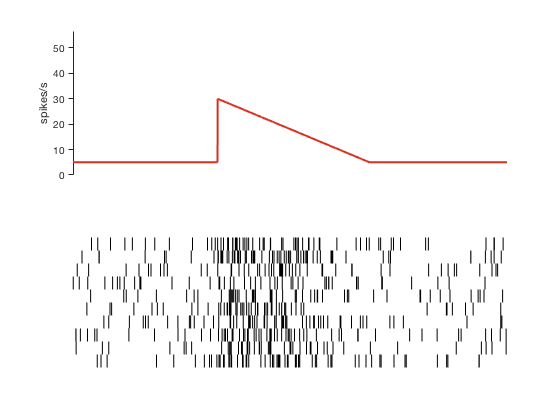


figure
subplot(2,1,1)
hold on
for idxTrial = 1:10
    plot(time, muP(idxTrial,:), 'color', [115,115,115]./255);
end
plot(time, mean(muP), 'color', [215,48,31]./255, 'linewidth', 2); 
xlim([13 19]);
ylim([0 max(mu(:))]);
ylabel('spikes/s')
set(gca, 'XTick' , []);
set(gca, 'XTickLabel', []);
set(gca,'XColor','w')
set(gca,'TickDir','out')
hold off
subplot(2,1,2)
LineFormat.Color =  'k';
plotSpikeRaster(b,'PlotType','vertline', 'VertSpikeHeight', 1,'XLimForCell',[13 19], 'LineFormat', LineFormat);
set(gca,'XColor','w')
set(gca,'YColor','w')

## auROC

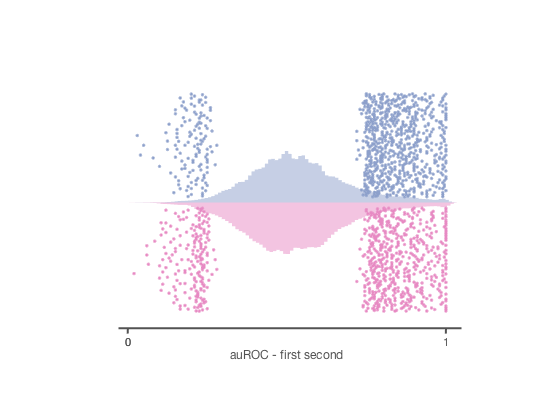

auROCCOA = [auRoccoa15;auRoccoaAA];
auROCPCX = [auRocpcx15;auRocpcxAA];
logSignificantCoa = [significancecoa15; significancecoaAA];
logSignificantCoa = logSignificantCoa(:);
logSignificantPcx = [significancepcx15; significancepcxAA];
logSignificantPcx = logSignificantPcx(:);

xMargin = 0.05 * range([auROCCOA(:); auROCPCX(:)]);
bottomMargin = 0;
topMargin = 0.001;
leftX = min([auROCCOA(:); auROCPCX(:)]);
rightX = max([auROCCOA(:); auROCPCX(:)]);
blankFigure([leftX-xMargin rightX+xMargin 0-bottomMargin 0.2+topMargin]);

distributionPlot(auROCCOA(:),'histOri','right','color',coaC,'widthDiv',[2 2],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
distributionPlot(auROCPCX(:),'histOri','left','color',pcxC,'widthDiv',[2 1],'showMM',0, 'globalNorm', 1, 'xyOri', 'flipped')
hold on
coaRsp = auROCCOA;
coaRsp(logSignificantCoa == 0) = [];
pcxRsp = auROCPCX;
pcxRsp(logSignificantPcx == 0) = [];
dataToPlot = {pcxRsp,coaRsp};
catIdx = [ones(length(pcxRsp),1); zeros(length(coaRsp),1)];
colori = {coaC, pcxC};
plotSpread(dataToPlot,'categoryIdx',catIdx,'categoryColors', colori, 'showMM', 0, 'xyOri', 'flipped')
alpha(0.5)

clear axP
start = floor(leftX-xMargin);
fin = ceil(rightX+xMargin);
axP.lineThickness = 2;
axP.axisLabel = 'auROC - first second';
axP.axisOrientation = 'h';
axP.tickLocations = [floor(leftX) 0 ceil(rightX)];
axP.tickLabels = {num2str(floor(leftX)), num2str(0), num2str(ceil(rightX))};
axP.axisOffset = 0.4;
axP.fontSize = 12; 
axP.color = labelC; 
AxisMMC(start, fin, axP);

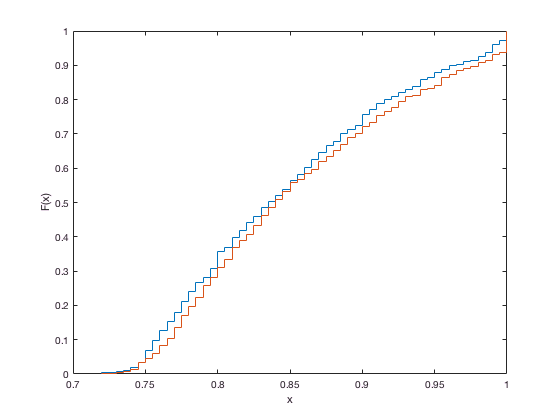


figure
ecdf(coaRsp(coaRsp>0.5))
hold on
ecdf(pcxRsp(pcxRsp>0.5))
hold off